# How is the retreat direction generated?

## Input variable

n is the number of key points which threat the end effector, you can change this value to see how the output changes.

n = 5;

## Initialize some varibles

According to n, a random position and velocity is generated for each of those key points. Here we assume that the distances between key points and ee are always in the interval [-0.15, 0,15], and the velocities of the key_points is in [-15, 15] (in each direction), the unit is in [m] and [m/s].

ee_position = [0, 0];

points_position = 0.15 .* (2 .* rand(n, 2) - ones(n,2));
points_vel = 15 .* (2 .* rand(n,2) - ones(n,2));

Next, we initialize some varibles for efficiency of calculation.

points_vec = zeros(size(points_position, 1),2);
distance = zeros(size(points_position, 1),1);

abs_points_vel = zeros(size(points_vel,1), 1);
ang_points_vel = zeros(size(points_vel, 1), 1);
eff_vel = zeros(size(points_vel, 1), 1);

## Get the essential factors

We will calculate a weight for each key point acoording to their positions and "effective velocities", i,e, the velocity component direct facing the end effector.

for i = 1:size(points_position, 1)
    points_vec(i, :) = ee_position - points_position(i, :);
    distance(i,1) = norm(points_vec(i,:)');
end

% Absolute value and angle of velocity
for i = 1:size(points_vel,1)
    abs_points_vel(i, 1) = norm(points_vel(i, :)');
    ang_points_vel(i, 1) = acosd(points_vel(i, :) * points_vec(i, :)' ./ (norm(points_vel(i, :)' * norm(points_vec(i, :)'))));
    % Because only the velocity direct facing the ee is critical, effective
    % velocity is calculated
    eff_vel(i, :) = cosd(ang_points_vel(i)).*abs_points_vel(i,:);
end

## Get the retreat parameters

We can get the weights for each key point from effective velocities and the distance, for intuitive matter, the weight functions of choosen is plotted in "Weight Functions"

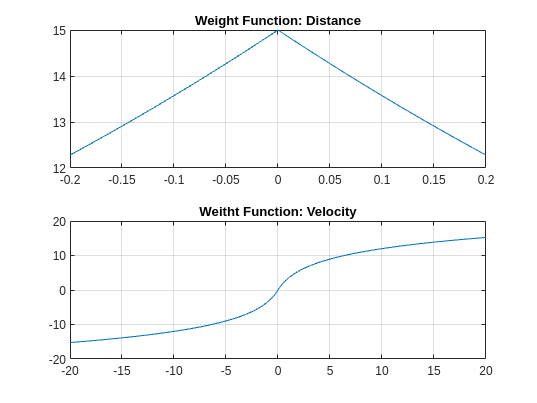

x_1 = -0.2:0.001:0.2;
y_1 = 15 .* exp(-abs(x_1));

x_2 = -20:0.1:20;
y_2 = sign(x_2) .* 5.0017 .* log(abs(x_2)+1);

figure(1)
subplot(2, 1, 1)
plot(x_1, y_1)
grid on
title("Weight Function: Distance")

subplot(2,1,2)
plot(x_2, y_2)
grid on
title("Weitht Function: Velocity")

According to the functions, we can get the weight as follows:

w_dist = 15 .* exp(-abs(distance));
w_vel = sign(eff_vel) .* 5.0017 .* log(abs(eff_vel)+1);

unit_vec = points_vec ./ distance;

w = (w_dist + w_vel)

w =     5.2037
   25.5844
   -0.1423
   26.4500
    2.6241



weighted_vec = w .* unit_vec;

retreat_dir = [sum(weighted_vec(:, 1)), sum(weighted_vec(:, 2)), 0];
unit_retreat_vec = retreat_dir ./ norm(retreat_dir);

## Visualization

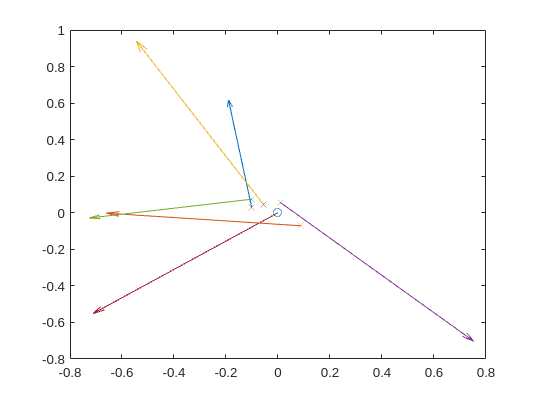

figure(2)
title ("Motion Directions")
% Plot the ee position
plot(0, 0, "o")
% text(0, 0, "end effector")

hold on

% Plot the key points
for i = 1:size(points_position, 1)
    plot(points_position(i, 1), points_position(i, 2), "x")
%    text(points_position(i, 1), points_position(i, 2), "key point")
end

% Plot the direction of retreat
quiver(0, 0, unit_retreat_vec(1), unit_retreat_vec(2))
%text(unit_retreat_vec(1), unit_retreat_vec(2), "end effector velocity")

% Plot the direction of the movement of key points
for i = 1:size(points_position, 1)
    quiver(points_position(i, 1), points_position(i, 2), points_vel(i, 1)/15, points_vel(i, 2)/15)
%    text(points_position(i, 1) + points_vel(i, 1)/15, points_position(i, 2) + points_vel(i, 2)/15, "key point velocity")
end